# **Final Vulcan Plotting**

## **Constants**

## Transfer in

TA_VK = deg2rad(180); % Hohmann transfer
gamma_kuat_arr = 0; % Hohmann transfer
v_inf_kuat_arr = 38.4517

v_inf_kuat_arr = 38.4517

e_kuat_arr = 1 + hgeo_kuat * v_inf_kuat_arr ^ 2 / mu_kuat

e_kuat_arr = 64.9202

a_kuat_arr = mu_kuat / v_inf_kuat_arr ^ 2

a_kuat_arr = 862.2058

eta_kuat_arr = acos(-1 / e_kuat_arr)

eta_kuat_arr = 1.5862

## Transfer out

eta_kuat_dep = acos(-1 / e_exit)

eta_kuat_dep = 1.5920

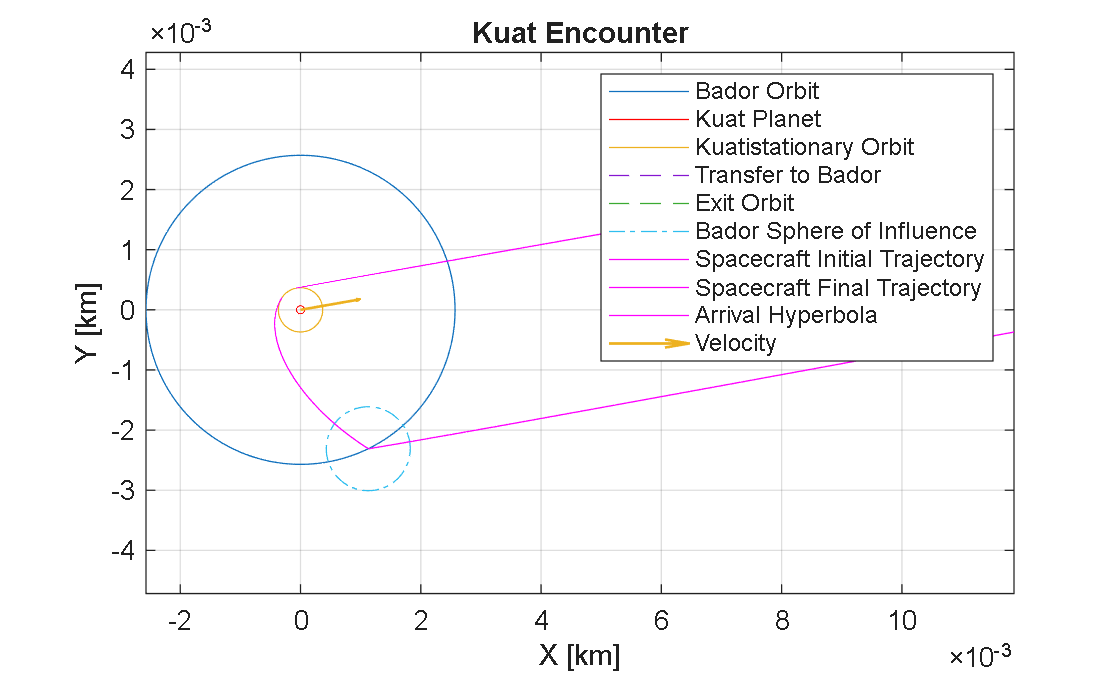

w_vulcan = deg2rad(100);
w_kuat = w_vulcan + TA_VK;
figure

w_offset = deg2rad(-18);

% Plot Bador
orbitplot2D(a_moon, e_moon, thetastar_moon, w_moon, "Bador Orbit", r_scale = AU);
% Plot Kuat
orbitplot2D(r_kaut, e_kuat_planet, thetastar_kuat_planet, w_kuat_planet, "Kuat Planet", r_scale = AU, color='r'); hold on
% Plot Kuatistationary
orbitplot2D(hgeo_kuat, e_kuat_geo, thetastar_kuat_geo, w_kuat_geo, "Kuatistationary Orbit", r_scale = AU);
% Plot transfer to Bador
orbitplot2D(a_trans2, e_trans2, -thetastar_trans2, -(w_trans2 - w_trans3 - eta_kuat_dep + w_kuat - pi / 2 + w_offset), "Transfer to Bador", r_scale = AU, LineStyle = "--");
% Plot transfer Out
orbitplot2D(a_hyp_kuat, e_exit, -thetastar_trans3, -(-eta_kuat_dep + w_kuat - pi / 2 + w_offset), "Exit Orbit", r_scale = AU, LineStyle = "--");
% Plot Bador Sphere of Influence
orbitplot2D(r_msoi, e_msoi, thetastar_msoi, 0, "Bador Sphere of Influence", r_scale = AU, origin = a_moon * [cosd(-82 - rad2deg(w_offset)); sind(-82 - rad2deg(w_offset))], LineStyle='-.');

% Plot transfer to Bador
orbitplot2D(a_trans2, e_trans2, -thetastar_trans2, -(w_trans2 - w_trans3 - eta_kuat_dep + w_kuat - pi / 2 + w_offset), "Spacecraft Initial Trajectory", r_scale = AU, LineStyle = "-", color='m');
% Plot transfer Out
orbitplot2D(a_hyp_kuat, e_exit, -thetastar_trans3, -(-eta_kuat_dep + w_kuat - pi /2 + w_offset), "Spacecraft Final Trajectory", r_scale = AU, LineStyle = "-", color='m');


orbitplot2D(a_kuat_arr, e_kuat_arr, -deg2rad(89):0.001:0, w_kuat + eta_kuat_arr - gamma_kuat_arr - pi / 2, "Arrival Hyperbola", r_scale = AU, color = "m")
%orbitplot2D(a_dep, e_dep, 0:0.001:deg2rad(100), w_vulcan - gamma_vulcan_dep - eta_dep - pi / 2, "Departure Hyp")

planet_velocity = 1e-3 * [-sin(w_kuat), cos(w_kuat)];
quiver(0, 0, planet_velocity(1), planet_velocity(2), "off", "filled", LineWidth = 1, DisplayName = "Velocity")
xlabel("X [km]")
ylabel("Y [km]")
grid on
axis equal
legend()
title("Kuat Encounter")
hold off